# Preconditioned Conjugate Gradient Method (PCG)

clear;

## PCG Function

function [x, r, r_norm, rel_res, k] = PCG_solver(A, b, x0, tol, kmax, M_lower)
% Solves Ax = b using the Preconditioned Conjugate Gradient method.
% Preconditioner M = M_lower * M_lower' (Incomplete Cholesky factor)
%
% Inputs:  A (SPD matrix), b (rhs), x0 (initial guess), tol, kmax
%          M_lower (lower triangular IC factor from ichol(A))
% Outputs: x (solution), r (residual), r_norm, rel_res, k (iterations)
%
% PCG implicitly solves M^{-1}*A*x = M^{-1}*b where M = L*L' is the
% IC factorization of A. This reduces the effective condition number
% and leads to significantly faster convergence than plain CG.
 
    x      = x0;
    r      = b - A * x;
 
    % Apply preconditioner: solve M*z = r via two triangular solves
    % This is the key step that distinguishes PCG from plain CG
    z      = M_lower' \ (M_lower \ r);
    p      = z;
 
    b_norm  = norm(b, 2);
    if b_norm == 0, b_norm = 1; end
 
    rz      = r' * z;
    r_norm  = norm(r, 2);
    rel_res = r_norm / b_norm;
    k       = 0;
 
    while rel_res > tol && k < kmax
 
        Ap    = A * p;
        alpha = rz / (p' * Ap);       % optimal step length
 
        x     = x + alpha * p;
        r_new = r - alpha * Ap;
 
        % Apply preconditioner to updated residual
        z_new  = M_lower' \ (M_lower \ r_new);
 
        rz_new = r_new' * z_new;
        beta   = rz_new / rz;         % direction update scalar
        p      = z_new + beta * p;    % new A-conjugate direction
 
        r      = r_new;
        z      = z_new;
        rz     = rz_new;
 
        k       = k + 1;
        r_norm  = norm(r, 2);
        rel_res = r_norm / b_norm;
 
    end
 
    if rel_res <= tol
        fprintf('Converged in %d iterations, rel. residual = %.2e\n', k, rel_res);
    else
        fprintf('Did not converge in %d iterations, rel. residual = %.2e\n', k, rel_res);
    end
 
end
 

## Test 1 — Small SPD system (n = 5)

n = 5;  rng(42);
R = rand(n);
A = sparse(R' * R + n * eye(n))   % sparse SPD by construction

A = 5×5 sparse double matrix (25 nonzeros)
   (1,1)       6.9627
   (2,1)       1.2180
   (3,1)       1.6946
   (4,1)       1.0461
   (5,1)       0.8661
   (1,2)       1.2180
   (2,2)       6.6407
   (3,2)       1.0370
   (4,2)       0.9667
   (5,2)       0.8998
   (1,3)       1.6946
   (2,3)       1.0370
   (3,3)       6.7123
   (4,3)       0.8804
   (5,3)       0.5518
   (1,4)       1.0461
   (2,4)       0.9667
   (3,4)       0.8804
   (4,4)       5.6730
   (5,4)       0.5990
   (1,5)       0.8661
   (2,5)       0.8998
   (3,5)       0.5518
   (4,5)       0.5990
   (5,5)       5.8214


x_exact = rand(n, 1)

x_exact =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


b = A * x_exact

b =     7.2415
    3.4300
    5.5365
    4.8557
    1.7687


 
% Compute Incomplete Cholesky preconditioner
M_lower = ichol(A)

M_lower = 5×5 sparse double matrix (15 nonzeros)
   (1,1)       2.6387
   (2,1)       0.4616
   (3,1)       0.6422
   (4,1)       0.3964
   (5,1)       0.3282
   (2,2)       2.5353
   (3,2)       0.2921
   (4,2)       0.3091
   (5,2)       0.2951
   (3,3)       2.4929
   (4,3)       0.2148
   (5,3)       0.1022
   (4,4)       2.3182
   (5,4)       0.1534
   (5,5)       2.3649


 
tol  = 1e-8;
kmax = 1000;
 
% Zero initial guess
[x1, r1, rn1, rr1, k1] = PCG_solver(A, b, zeros(n,1), tol, kmax, M_lower)

Converged in 1 iterations, rel. residual = 2.56e-16


x1 =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


r1 = 1.0e-14 *

   -0.0888
   -0.1776
   -0.0888
   -0.1776
   -0.0222


rn1 = 2.8174e-15

rr1 = 2.5554e-16

k1 = 1

fprintf('||r||_2 = %.4e,  abs. error = %.4e\n', rn1, norm(x1 - x_exact, 2))

||r||_2 = 2.8174e-15,  abs. error = 3.3602e-16


 
% Random initial guess
[x2, ~, rn2, ~, k2] = PCG_solver(A, b, rand(n,1), tol, kmax, M_lower)

Converged in 1 iterations, rel. residual = 4.27e-17


x2 =     0.7852
    0.1997
    0.5142
    0.5924
    0.0465


rn2 = 4.7103e-16

k2 = 1

fprintf('Random x0 - abs. error = %.4e\n', norm(x2 - x_exact, 2))

Random x0 - abs. error = 2.2204e-16


## Test 2 — Scaling with system size: n = 100, 1000, 3000


sizes = [100, 1000, 3000];
fprintf('\n  n       Iters   ||r||_2      RelRes       CPU(s)\n')


  n       Iters   ||r||_2      RelRes       CPU(s)


 
for i = 1:length(sizes)
    n = sizes(i);  rng(i);
    R = rand(n);
    A = sparse(R' * R + n * eye(n));
    x_exact = rand(n, 1);
    b = A * x_exact;
 
    opts.type    = 'ict';
    opts.droptol = 1e-3;
    M_lower = ichol(A, opts);
 
    tic;
    [x_s, ~, rn_s, rr_s, k_s] = PCG_solver(A, b, zeros(n,1), 1e-8, 5000, M_lower);
    t_s = toc;
    fprintf('  %-7d %-7d %-12.4e %-12.4e %.4f\n', n, k_s, rn_s, rr_s, t_s)
end

Converged in 5 iterations, rel. residual = 1.02e-09


  100     5       1.4341e-05   1.0150e-09   0.0089


Error using ichol
Encountered nonpositive pivot.

## Test 3 — Sparse matrix: 1D Poisson (FDM, Lecture 8)

n_sp     = 500;
e        = ones(n_sp, 1);
A_sparse = spdiags([-e, 4*e, -e], -1:1, n_sp, n_sp) + speye(n_sp);
x_exact  = ones(n_sp, 1);
b_sp     = A_sparse * x_exact;
 
opts.type   = 'ict';
opts.droptol = 1e-3;
opts.diagcomp = 0.1;
M_lower_sp = ichol(A_sparse, opts)

M_lower_sp = 500×500 sparse double matrix (999 nonzeros)
   (1,1)       2.3452
   (2,1)      -0.4264
   (2,2)       2.3061
   (3,2)      -0.4336
   (3,3)       2.3048
   (4,3)      -0.4339
   (4,4)       2.3047
   (5,4)      -0.4339
   (5,5)       2.3047
   (6,5)      -0.4339
   (6,6)       2.3047
   (7,6)      -0.4339
   (7,7)       2.3047
   (8,7)      -0.4339
   (8,8)       2.3047
   (9,8)      -0.4339
   (9,9)       2.3047
  (10,9)      -0.4339
  (10,10)      2.3047
  (11,10)     -0.4339
  (11,11)      2.3047
  (12,11)     -0.4339
  (12,12)      2.3047
  (13,12)     -0.4339
  (13,13)      2.3047
  (14,13)     -0.4339
  (14,14)      2.3047
  (15,14)     -0.4339
  (15,15)      2.3047
  (16,15)     -0.4339
  (16,16)      2.3047
  (17,16)     -0.4339
  (17,17)      2.3047
  (18,17)     -0.4339
  (18,18)      2.3047
  (19,18)     -0.4339
  (19,19)      2.3047
  (20,19)     -0.4339
  (20,20)      2.3047
  (21,20)     -0.4339
  (21,21)      2.3047
  (22,21)     -0.4339
  (22,22)      2.30

 
fprintf('\nSparse test (n=%d, nnz=%d)\n', n_sp, nnz(A_sparse))


Sparse test (n=500, nnz=1498)


tic;
[x_sp, ~, rn_sp, rr_sp, k_sp] = PCG_solver(A_sparse, b_sp, zeros(n_sp,1), 1e-8, 10000, M_lower_sp)

Converged in 5 iterations, rel. residual = 6.14e-10


x_sp =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


rn_sp = 4.1248e-08

rr_sp = 6.1394e-10

k_sp = 5

t_sp = toc;
fprintf('Iters = %d,  abs. error = %.4e,  CPU = %.4f s\n', ...
    k_sp, norm(x_sp - x_exact, 2), t_sp)

Iters = 5,  abs. error = 9.4020e-09,  CPU = 0.0414 s


## Test 4 — Comparison with MATLAB built-in pcg() using IC preconditioner



n_c  = 300;  rng(7);
R    = rand(n_c);
A_c  = sparse(R' * R + n_c * eye(n_c));
x_ec = rand(n_c, 1);
b_c  = A_c * x_ec;
 
opts.type    = 'ict';
opts.droptol = 1e-3;
M_c = ichol(A_c, opts);

Error using ichol
Encountered nonpositive pivot.

 
tic;
[x_our, ~, rn_our, ~, k_our] = PCG_solver(A_c, b_c, zeros(n_c,1), 1e-8, 5000, M_c)
t_our = toc;
 
tic;
[x_ml, ~, ~, k_ml] = pcg(A_c, b_c, 1e-8, 5000, M_c, M_c')
t_ml = toc;
rn_ml = norm(b_c - A_c * x_ml, 2)
 
fprintf('\n               Iters   ||r||_2      AbsError     CPU(s)\n')
fprintf('  PCG_solver   %-7d %-12.4e %-12.4e %.4f\n', k_our, rn_our, norm(x_our-x_ec,2), t_our)
fprintf('  MATLAB pcg() %-7d %-12.4e %-12.4e %.4f\n', k_ml,  rn_ml,  norm(x_ml-x_ec,2),  t_ml)

## Test 5 — CG vs PCG: effect of preconditioning on convergence

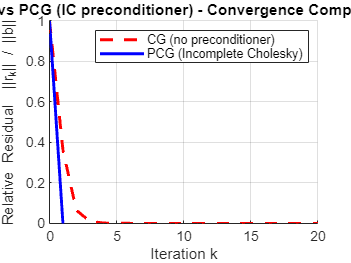

n_cv     = 200;
e        = ones(n_cv, 1);
A_cv     = spdiags([-e, 4*e, -e], -1:1, n_cv, n_cv) + speye(n_cv);
x_ex_cv  = rand(n_cv, 1);
b_cv     = A_cv * x_ex_cv;
x0_cv    = zeros(n_cv, 1);
bn_cv    = norm(b_cv, 2);
tol_cv   = 1e-10;
 
% Plain CG - track residual history
r_cg  = b_cv;
p_cg  = r_cg;
x_cg  = x0_cv;
hist_cg = [];
hist_cg(1) = norm(r_cg,2) / bn_cv;
 
for ki = 1:n_cv
    Ap       = A_cv * p_cg;
    rTr      = r_cg' * r_cg;
    alpha    = rTr / (p_cg' * Ap);
    x_cg     = x_cg + alpha * p_cg;
    r_new    = r_cg - alpha * Ap;
    beta     = (r_new' * r_new) / rTr;
    p_cg     = r_new + beta * p_cg;
    r_cg     = r_new;
    hist_cg(end+1) = norm(r_cg,2) / bn_cv;
    if hist_cg(end) < 1e-13, break; end
end
 
% PCG with IC - track residual history
M_cv   = ichol(A_cv);
r_pcg  = b_cv;
z_pcg  = M_cv' \ (M_cv \ r_pcg);
p_pcg  = z_pcg;
x_pcg  = x0_cv;
rz_pcg = r_pcg' * z_pcg;
hist_pcg = [];
hist_pcg(1) = norm(r_pcg,2) / bn_cv;
 
for ki = 1:n_cv
    Ap       = A_cv * p_pcg;
    alpha    = rz_pcg / (p_pcg' * Ap);
    x_pcg    = x_pcg + alpha * p_pcg;
    r_new    = r_pcg - alpha * Ap;
    z_new    = M_cv' \ (M_cv \ r_new);
    rz_new   = r_new' * z_new;
    beta     = rz_new / rz_pcg;
    p_pcg    = z_new + beta * p_pcg;
    r_pcg    = r_new;
    rz_pcg   = rz_new;
    hist_pcg(end+1) = norm(r_pcg,2) / bn_cv;
    if hist_pcg(end) < 1e-13, break; end
end
 
figure; hold on; grid on;
semilogy(0:length(hist_cg)-1,  hist_cg,  'r--', 'LineWidth', 2)
semilogy(0:length(hist_pcg)-1, hist_pcg, 'b-',  'LineWidth', 2)
xlabel('Iteration k')
ylabel('Relative Residual  ||r_k|| / ||b||')
title('CG vs PCG (IC preconditioner) - Convergence Comparison')
legend('CG (no preconditioner)', 'PCG (Incomplete Cholesky)', 'Location', 'northeast')

 
% PCG converges in fewer iterations - IC reduces effective condition number.

%% Test 6 - Matrix Market sparse matrix (gr_30_30)
%  Real sparse SPD matrix loaded from Matrix Market database
%  Size: 900 x 900

addpath('C:\Users\gorio\Documents')
A_mm       = mmread('gr_30_30.mtx');
x_exact_mm = ones(900, 1);
b_mm       = A_mm * x_exact_mm;
x0_mm      = zeros(900, 1);

% PCG on Matrix Market matrix
M_mm = ichol(A_mm);
tic;
[x_pcg_mm, ~, rn_pcg, rr_pcg, k_pcg] = PCG_solver(A_mm, b_mm, x0_mm, 1e-8, 5000, M_mm);
t_pcg = toc;
fprintf('PCG Iters=%d, rn=%.4e, err=%.4e, CPU=%.4f\n', ...
    k_pcg, rn_pcg, norm(x_pcg_mm - x_exact_mm, 2), t_pcg)

% CG vs PCG convergence comparison plot
n_cv     = 200;
e        = ones(n_cv, 1);
A_cv     = spdiags([-e, 4*e, -e], -1:1, n_cv, n_cv) + speye(n_cv);
b_cv     = A_cv * rand(n_cv, 1);
x0_cv    = zeros(n_cv, 1);
bn_cv    = norm(b_cv, 2);

% Plain CG history
r_cg  = b_cv;
p_cg  = r_cg;
x_cg  = x0_cv;
hist_cg = norm(r_cg,2) / bn_cv;

for ki = 1:n_cv
    Ap       = A_cv * p_cg;
    rTr      = r_cg' * r_cg;
    alpha    = rTr / (p_cg' * Ap);
    x_cg     = x_cg + alpha * p_cg;
    r_new    = r_cg - alpha * Ap;
    beta     = (r_new' * r_new) / rTr;
    p_cg     = r_new + beta * p_cg;
    r_cg     = r_new;
    hist_cg(end+1) = norm(r_cg,2) / bn_cv;
    if hist_cg(end) < 1e-13, break; end
end

% PCG with IC history
opts2.type     = 'ict';
opts2.droptol  = 1e-3;
opts2.diagcomp = 0.1;
M_cv   = ichol(A_cv, opts2);
r_pcg2  = b_cv;
z_pcg   = M_cv' \ (M_cv \ r_pcg2);
p_pcg   = z_pcg;
x_pcg2  = x0_cv;
rz_pcg  = r_pcg2' * z_pcg;
hist_pcg = norm(r_pcg2,2) / bn_cv;

for ki = 1:n_cv
    Ap       = A_cv * p_pcg;
    alpha    = rz_pcg / (p_pcg' * Ap);
    x_pcg2   = x_pcg2 + alpha * p_pcg;
    r_new    = r_pcg2 - alpha * Ap;
    z_new    = M_cv' \ (M_cv \ r_new);
    rz_new   = r_new' * z_new;
    beta     = rz_new / rz_pcg;
    p_pcg    = z_new + beta * p_pcg;
    r_pcg2   = r_new;
    rz_pcg   = rz_new;
    hist_pcg(end+1) = norm(r_pcg2,2) / bn_cv;
    if hist_pcg(end) < 1e-13, break; end
end

figure; hold on; grid on;
semilogy(0:length(hist_cg)-1,  hist_cg,  'r--', 'LineWidth', 2)
semilogy(0:length(hist_pcg)-1, hist_pcg, 'b-',  'LineWidth', 2)
xlabel('Iteration k')
ylabel('Relative Residual ||r\_k|| / ||b||')
title('CG vs PCG (IC) - Convergence Comparison')
legend('CG (no preconditioner)', 'PCG (Incomplete Cholesky)', ...
    'Location', 'northeast')
saveas(gcf, 'C:\Users\gorio\Documents\cg_vs_pcg.png')